# Small Network

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [pwd '/Figures/Demo042421-1/'];
addpath(DataFolder)
OldDataFolder = [pwd '/Figures/Demo042421/'];
addpath(OldDataFolder)
% Make sure the old stuff is the same
load('NtWk_Archit.mat')
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2))*0.75; 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2))*0.75; %Plan A:Original
                                                                           %Plan B: Lower #ItoE and #I-to-I

% Now Make a small network s.t. the mean presynaptic neurons are equal to
% above
N_E = floor(1.5*N_IE); N_I = floor(1/3*N_E);
CS_EE = SmallNetworkGenerat(N_E,N_E,N_EE);
CS_IE = SmallNetworkGenerat(N_E,N_I,N_IE);
CS_EI = SmallNetworkGenerat(N_I,N_E,N_EI);
CS_II = SmallNetworkGenerat(N_I,N_I,N_II);

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80; % 80
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.6;  % was 1.52
                                 % Plan B: Increase S_EI to compensate
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

Now: Delete L6 and amb, and transfer all to LGN.

S_ambU = S_EE; % there is only one Samb...So all align to E
rE_ambU = rE_amb*S_amb/S_ambU; rI_ambU = rI_amb*S_amb/S_ambU;
S_EL6U = S_Elgn; S_IL6U = S_Ilgn;
rE_L6U = rE_L6*S_EL6/S_EL6U;     rI_L6U = rI_L6*S_IL6/S_IL6U; %250hz for now

## Network Simulation

Elapsed time is 0.569574 seconds.
Elapsed time is 0.807550 seconds.
Elapsed time is 1.047942 seconds.
Elapsed time is 1.282943 seconds.
Elapsed time is 1.527071 seconds.
Elapsed time is 1.775348 seconds.
Elapsed time is 2.005287 seconds.
Elapsed time is 2.246269 seconds.


S_EE = 0.024, S_EI = 0.0384, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

Elapsed time is 2.816026 seconds.
Elapsed time is 3.054462 seconds.
Elapsed time is 3.291000 seconds.
Elapsed time is 3.535297 seconds.
Elapsed time is 3.776656 seconds.
Elapsed time is 4.031768 seconds.
Elapsed time is 4.301254 seconds.
Elapsed time is 4.548895 seconds.
Elapsed time is 4.793030 seconds.
Elapsed time is 5.048799 seconds.


S_EE = 0.024, S_EI = 0.0384, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

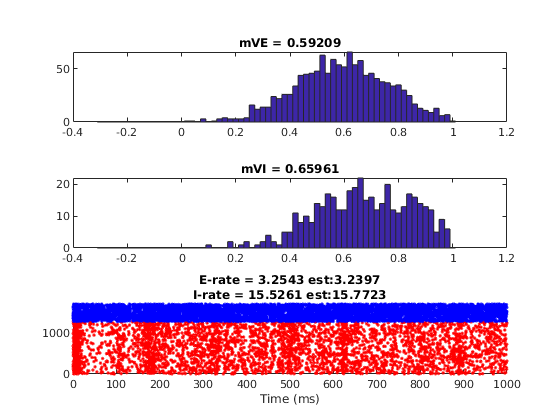

Elapsed time is 5.507092 seconds.
Elapsed time is 5.760146 seconds.
Elapsed time is 6.011117 seconds.
Elapsed time is 6.258852 seconds.
Elapsed time is 6.513172 seconds.
Elapsed time is 6.762120 seconds.
Elapsed time is 7.019287 seconds.
Elapsed time is 7.269781 seconds.
Elapsed time is 7.537091 seconds.
Elapsed time is 7.786632 seconds.


S_EE = 0.024, S_EI = 0.0384, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

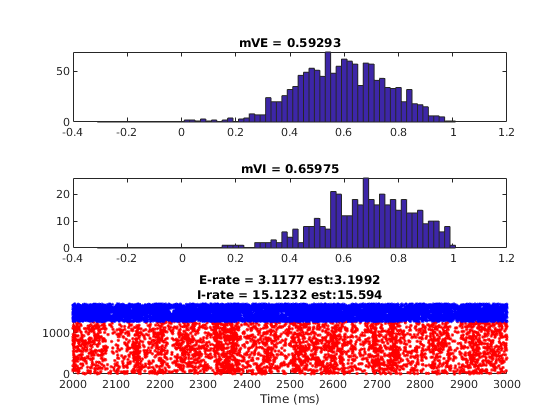

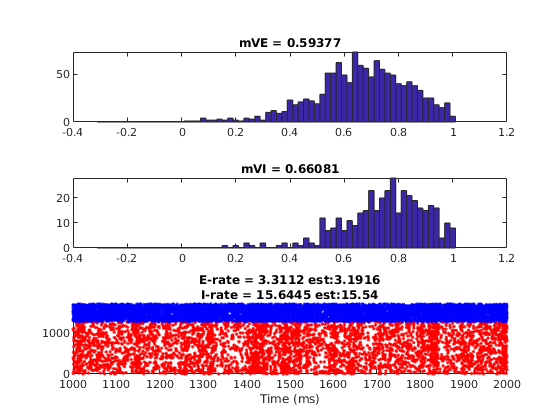

Elapsed time is 8.258814 seconds.


E_Ind = 1:N_E; I_Ind = 1:N_I;

%% Network Simulation
T = 3000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = 0.5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = 0.5; N_EIDly = floor(T_EIDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

N_EE = mean(sum(CS_EE,2)); N_EI = mean(sum(CS_EI,2));
N_IE = mean(sum(CS_IE,2)); N_II = mean(sum(CS_II,2));

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
load('IniTestSNW.mat');
RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
                                                             GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
RefTimeI = EndState{10};VI = EndState{11};SpI = EndState{12};GI_ampa_R = EndState{13};GI_nmda_R = EndState{14};GI_gaba_R = EndState{15};
                                                             GI_ampa_D = EndState{16};GI_nmda_D = EndState{17};GI_gaba_D = EndState{18};
if N_EEDly>=size(EndState{19},2)
EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
else
    EEDlyRcd = EndState{19}(:,1:N_EEDly);
end
if N_IEDly>=size(EndState{20},2)
IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
else
    IEDlyRcd = EndState{20}(:,1:N_IEDly);
end
EIDlyRcd = sparse(N_E,N_EIDly);
%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver3_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        CS_EE,CS_EI,CS_IE,CS_II,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_ambU,lambda_E,lambda_I,rE_ambU,rI_ambU,...
        S_EL6U,S_IL6U,rE_L6U,rI_L6U); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        %E_Ind = 10000:13000; I_Ind = 3300:4300;
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        %close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
        toc
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end

toc

Elapsed time is 8.262759 seconds.



NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop


## Now, with drive

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

- Kicks are all normalized to LGN sizes

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lgnE_Drive = [60,50,42,50]*4/1e3;
lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(1);
lambda_I_drive = lgnI_Drive;

L6E_Drive = [50 35 20 35]*50/1e3;
L6I_Drive = min(L6E_Drive);
rE_L6_DriveU = L6E_Drive(1)*S_EL6/S_EL6U;
rI_L6_DriveU = 3*rE_L6_DriveU*S_IL6/S_IL6U;


% Making Poisson here/Reading
T = 50000; dt = 0.1;
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_ambU,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_ambU,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_DriveU*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_DriveU*(1-L6CurInp),T*TimeFrac,dt);

%   [A,~,Times] = find(eventsN);

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = 0.5; N_EIDly = floor(T_EIDly/dt);
% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation 
%load(['DriveWkSp_TestDly_EE0.8_IE0.8_17.mat'],'EndState');
load('DriveWk_SNW_Sp_TestDly_EE0.9_IE0.5_NMDA80_40-45_C.mat','EndState');
RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
                                                             GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
                                                                GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
if N_EEDly>=size(EndState{19},2)
EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
else
    EEDlyRcd = EndState{19}(:,1:N_EEDly);
end
if N_IEDly>=size(EndState{20},2)
IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
else
    IEDlyRcd = EndState{20}(:,1:N_IEDly);
end
if N_EIDly>=size(EndState{21},2)
EIDlyRcd = [EndState{21},zeros(N_E,N_EIDly-size(EndState{20},2))]; 
else
    EIDlyRcd = EndState{21}(:,1:N_EIDly);
end
%EIDlyRcd = repmat(CS_EI*SpI,1,N_EIDly);
% Create sliding windows
sampleT = 200;
Sliding = 200;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

But to accelerate, we exclude L6 Current Input at first...

TPar = 10;
TSimOne = floor(T/TPar/1e3);

## Simulations of drive

for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) + lambda_E_drive*dt*LGNCurInp) ...
                      + S_ambU  * AmbE_Events(:,RandTimBin(3,:)) ...
                      + S_EL6U  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_DriveU*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                      + S_ambU  * AmbI_Events(:,RandTimBin(4,:)) ...
                      + S_IL6U  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_DriveU*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6U  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_DriveU*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6U  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_DriveU*dt*L6CurInp) * rhoI_ampa));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
     
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                          GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                          RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                          GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                          EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          CS_EE,CS_EI,CS_IE,CS_II,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;
    
     
    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.5;
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs= I_Sp;
              
        SampleInd = SampleInd + 1
        sum(isnan(oVE))/N_E       
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 1
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
%DataFolder = [pwd '/Figures/Demo042221/'];
text = sprintf('DriveWk_SNW_Sp_TestDly_EE%.1f_IE%.1f_NMDA%d_%d-%d_D.mat',T_EEDly,T_IEDly, tau_nmda_D,...
                                                     TSimOne*(TSec-1),TSimOne*TSec);
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd, EIDlyRcd};
save([DataFolder text],'NWTrace','EndState','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
end

SampleInd = 27

ans = 0.1414

SampleInd = 28

ans = 0.0671

SampleInd = 29

ans = 0.0861

SampleInd = 30

ans = 0.0727

SampleInd = 31

ans = 0.0458

SampleInd = 32

ans = 0.0640

SampleInd = 33

ans = 0.0774

SampleInd = 34

ans = 0.0814

SampleInd = 35

ans = 0.1137

SampleInd = 36

ans = 0.0600

SampleInd = 37

ans = 0.0932

SampleInd = 38

ans = 0.0908

SampleInd = 39

ans = 0.0900

SampleInd = 40

ans = 0.0742

SampleInd = 41

ans = 0.0411

SampleInd = 42

ans = 0.0940

SampleInd = 43

ans = 0.0932

SampleInd = 44

ans = 0.0687

SampleInd = 45

ans = 0.1058

SampleInd = 46

ans = 0.0569

SampleInd = 47

ans = 0.0908

SampleInd = 48

ans = 0.0790

SampleInd = 49

ans = 0.0450

SampleInd = 50

ans = 0.0656

SampleInd = 51

ans = 0.0577

Elapsed time is 15.848633 seconds.


SampleInd = 52

ans = 0.0624

SampleInd = 53

ans = 0.0687

SampleInd = 54

ans = 0.1359

SampleInd = 55

ans = 0.0482

SampleInd = 56

ans = 0.0411

SampleInd = 57

ans = 0.0545

SampleInd = 58

ans = 0.0750

SampleInd = 59

ans = 0.1517

SampleInd = 60

ans = 0.0561

SampleInd = 61

ans = 0.0513

SampleInd = 62

ans = 0.1011

SampleInd = 63

ans = 0.0956

SampleInd = 64

ans = 0.0908

SampleInd = 65

ans = 0.0790

SampleInd = 66

ans = 0.1335

SampleInd = 67

ans = 0.0758

SampleInd = 68

ans = 0.0632

SampleInd = 69

ans = 0.1122

SampleInd = 70

ans = 0.0956

SampleInd = 71

ans = 0.0458

SampleInd = 72

ans = 0.0814

SampleInd = 73

ans = 0.0671

SampleInd = 74

ans = 0.0474

SampleInd = 75

ans = 0.0932

SampleInd = 76

ans = 0.0893

Elapsed time is 15.751258 seconds.


SampleInd = 77

ans = 0.0964

SampleInd = 78

ans = 0.0561

SampleInd = 79

ans = 0.1027

SampleInd = 80

ans = 0.1058

SampleInd = 81

ans = 0.0806

SampleInd = 82

ans = 0.0924

SampleInd = 83

ans = 0.1082

SampleInd = 84

ans = 0.1769

SampleInd = 85

ans = 0.0521

SampleInd = 86

ans = 0.0719

SampleInd = 87

ans = 0.1019

SampleInd = 88

ans = 0.0861

SampleInd = 89

ans = 0.0727

SampleInd = 90

ans = 0.0608

SampleInd = 91

ans = 0.1019

SampleInd = 92

ans = 0.0632

SampleInd = 93

ans = 0.0948

SampleInd = 94

ans = 0.1153

SampleInd = 95

ans = 0.0861

SampleInd = 96

ans = 0.0916

SampleInd = 97

ans = 0.0640

SampleInd = 98

ans = 0.0671

SampleInd = 99

ans = 0.0758

SampleInd = 100

ans = 0.0932

SampleInd = 101

ans = 0.0727

Elapsed time is 15.940504 seconds.


SampleInd = 102

ans = 0.0750

SampleInd = 103

ans = 0.0948

SampleInd = 104

ans = 0.0624

SampleInd = 105

ans = 0.0577

SampleInd = 106

ans = 0.0995

SampleInd = 107

ans = 0.0695

SampleInd = 108

ans = 0.0419

SampleInd = 109

ans = 0.0695

SampleInd = 110

ans = 0.0553

SampleInd = 111

ans = 0.0758

SampleInd = 112

ans = 0.1248

SampleInd = 113

ans = 0.0766

SampleInd = 114

ans = 0.0624

SampleInd = 115

ans = 0.0908

SampleInd = 116

ans = 0.0750

SampleInd = 117

ans = 0.0703

SampleInd = 118

ans = 0.0900

SampleInd = 119

ans = 0.1098

SampleInd = 120

ans = 0.0506

SampleInd = 121

ans = 0.1130

SampleInd = 122

ans = 0.0703

SampleInd = 123

ans = 0.0687

SampleInd = 124

ans = 0.0790

SampleInd = 125

ans = 0.0553

SampleInd = 126

ans = 0.0727

Elapsed time is 15.837110 seconds.


SampleInd = 127

ans = 0.0640

SampleInd = 128

ans = 0.0640

SampleInd = 129

ans = 0.1153

SampleInd = 130

ans = 0.1509

SampleInd = 131

ans = 0.0679

SampleInd = 132

ans = 0.0916

SampleInd = 133

ans = 0.0956

SampleInd = 134

ans = 0.0940

SampleInd = 135

ans = 0.0679

SampleInd = 136

ans = 0.0371

SampleInd = 137

ans = 0.0608

SampleInd = 138

ans = 0.1098

SampleInd = 139

ans = 0.0719

SampleInd = 140

ans = 0.0450

SampleInd = 141

ans = 0.1019

SampleInd = 142

ans = 0.0537

SampleInd = 143

ans = 0.0964

SampleInd = 144

ans = 0.0411

SampleInd = 145

ans = 0.0442

SampleInd = 146

ans = 0.0987

SampleInd = 147

ans = 0.1058

SampleInd = 148

ans = 0.0648

SampleInd = 149

ans = 0.0711

SampleInd = 150

ans = 0.1090

SampleInd = 151

ans = 0.0782

Elapsed time is 15.824322 seconds.


SampleInd = 152

ans = 0.1058

SampleInd = 153

ans = 0.1051

SampleInd = 154

ans = 0.0845

SampleInd = 155

ans = 0.1066

SampleInd = 156

ans = 0.0624

SampleInd = 157

ans = 0.0664

SampleInd = 158

ans = 0.0790

SampleInd = 159

ans = 0.0679

SampleInd = 160

ans = 0.0829

SampleInd = 161

ans = 0.0956

SampleInd = 162

ans = 0.0790

SampleInd = 163

ans = 0.0600

SampleInd = 164

ans = 0.1043

SampleInd = 165

ans = 0.0979

SampleInd = 166

ans = 0.0395

SampleInd = 167

ans = 0.0774

SampleInd = 168

ans = 0.1351

SampleInd = 169

ans = 0.0711

SampleInd = 170

ans = 0.0829

SampleInd = 171

ans = 0.1003

SampleInd = 172

ans = 0.1185

SampleInd = 173

ans = 0.0632

SampleInd = 174

ans = 0.0632

SampleInd = 175

ans = 0.0853

SampleInd = 176

ans = 0.0829

Elapsed time is 15.967379 seconds.


SampleInd = 177

ans = 0.1185

SampleInd = 178

ans = 0.0782

SampleInd = 179

ans = 0.0679

SampleInd = 180

ans = 0.0545

SampleInd = 181

ans = 0.1351

SampleInd = 182

ans = 0.0735

SampleInd = 183

ans = 0.0466

SampleInd = 184

ans = 0.1027

SampleInd = 185

ans = 0.0387

SampleInd = 186

ans = 0.1438

SampleInd = 187

ans = 0.0703

SampleInd = 188

ans = 0.0427

SampleInd = 189

ans = 0.0869

SampleInd = 190

ans = 0.0664

SampleInd = 191

ans = 0.0600

SampleInd = 192

ans = 0.0671

SampleInd = 193

ans = 0.0545

SampleInd = 194

ans = 0.0735

SampleInd = 195

ans = 0.0490

SampleInd = 196

ans = 0.0774

SampleInd = 197

ans = 0.0671

SampleInd = 198

ans = 0.1209

SampleInd = 199

ans = 0.0924

SampleInd = 200

ans = 0.0861

SampleInd = 201

ans = 0.1343

Elapsed time is 16.017416 seconds.


SampleInd = 202

ans = 0.0656

SampleInd = 203

ans = 0.0506

SampleInd = 204

ans = 0.0513

SampleInd = 205

ans = 0.0648

SampleInd = 206

ans = 0.0648

SampleInd = 207

ans = 0.0790

SampleInd = 208

ans = 0.1035

SampleInd = 209

ans = 0.0608

SampleInd = 210

ans = 0.1003

SampleInd = 211

ans = 0.0703

SampleInd = 212

ans = 0.0861

SampleInd = 213

ans = 0.0592

SampleInd = 214

ans = 0.0821

SampleInd = 215

ans = 0.0727

SampleInd = 216

ans = 0.0932

SampleInd = 217

ans = 0.0316

SampleInd = 218

ans = 0.0908

SampleInd = 219

ans = 0.0995

SampleInd = 220

ans = 0.0940

SampleInd = 221

ans = 0.0458

SampleInd = 222

ans = 0.1011

SampleInd = 223

ans = 0.0948

SampleInd = 224

ans = 0.0829

SampleInd = 225

ans = 0.1240

SampleInd = 226

ans = 0.0632

Elapsed time is 15.744972 seconds.


SampleInd = 227

ans = 0.0908

SampleInd = 228

ans = 0.0798

SampleInd = 229

ans = 0.0632

SampleInd = 230

ans = 0.0537

SampleInd = 231

ans = 0.0640

SampleInd = 232

ans = 0.0900

SampleInd = 233

ans = 0.1130

SampleInd = 234

ans = 0.0506

SampleInd = 235

ans = 0.0821

SampleInd = 236

ans = 0.1240

SampleInd = 237

ans = 0.0545

SampleInd = 238

ans = 0.0782

SampleInd = 239

ans = 0.0956

SampleInd = 240

ans = 0.0585

SampleInd = 241

ans = 0.0592

SampleInd = 242

ans = 0.0616

SampleInd = 243

ans = 0.0561

SampleInd = 244

ans = 0.0679

SampleInd = 245

ans = 0.0703

SampleInd = 246

ans = 0.0411

SampleInd = 247

ans = 0.1256

SampleInd = 248

ans = 0.1011

SampleInd = 249

ans = 0.0987

SampleInd = 250

ans = 0.0719

SampleInd = 251

ans = 0.0845

Elapsed time is 15.951649 seconds.


SampleInd = 252

ans = 0.0948

SampleInd = 253

ans = 0.0592

SampleInd = 254

ans = 0.0371

SampleInd = 255

ans = 0.0679

SampleInd = 256

ans = 0.0750

SampleInd = 257

ans = 0.0711

SampleInd = 258

ans = 0.1043

SampleInd = 259

ans = 0.1011

SampleInd = 260

ans = 0.0482

SampleInd = 261

ans = 0.0782

SampleInd = 262

ans = 0.0908

SampleInd = 263

ans = 0.1272

SampleInd = 264

ans = 0.0308

SampleInd = 265

ans = 0.0869

SampleInd = 266

ans = 0.1327

SampleInd = 267

ans = 0.0829

SampleInd = 268

ans = 0.0774

SampleInd = 269

ans = 0.1003

SampleInd = 270

ans = 0.1311

SampleInd = 271

ans = 0.0608

SampleInd = 272

ans = 0.0379

SampleInd = 273

ans = 0.0553

SampleInd = 274

ans = 0.0553

SampleInd = 275

ans = 0.0442

SampleInd = 276

ans = 0.0798

Elapsed time is 15.996648 seconds.


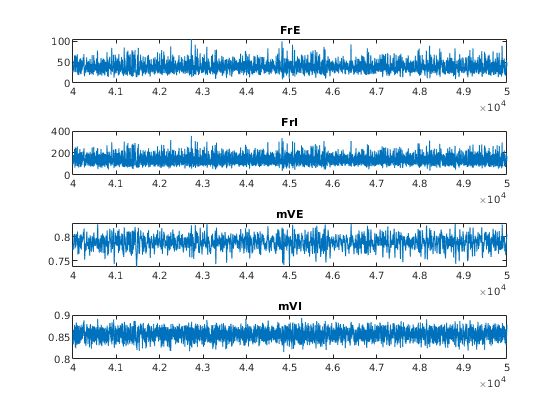

%DataFolder = [pwd '/Figures/Demo042221/'];
TPar = 10;
% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 1:TPar
    text = sprintf('DriveWk_SNW_Sp_TestDly_EE%.1f_IE%.1f_NMDA%d_%d-%d_D.mat',T_EEDly,T_IEDly, tau_nmda_D,...
                                                     TSimOne*(TSec-1),TSimOne*TSec);
    load([DataFolder text],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end
WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
WinSize = StatWin(2) - StatWin(1);

SNWData.VE = nanmean(mVE);
SNWData.VI = nanmean(mVI);
SNWData.SpE = histcounts(SpE(:,2),StatWin);
SNWData.SpI = histcounts(SpI(:,2),StatWin);

Smth = 10;
SNWData.VE = conv(SNWData.VE,1/Smth*ones(1,Smth)); SNWData.VE = SNWData.VE(Smth:end-Smth+1);
SNWData.VI = conv(SNWData.VI,1/Smth*ones(1,Smth)); SNWData.VI = SNWData.VI(Smth:end-Smth+1);
SNWData.SpE = conv(SNWData.SpE,1/Smth*ones(1,Smth)); SNWData.SpE = SNWData.SpE(Smth:end-Smth+1);
SNWData.SpI = conv(SNWData.SpI,1/Smth*ones(1,Smth)); SNWData.SpI = SNWData.SpI(Smth:end-Smth+1);

figure("Name",'Traj on Time')
subplot 411
plot(StatWin(1:end-Smth),SNWData.SpE/N_E/WinSize*1e3)
title('FrE');xlim([4e4 5e4])
subplot 412
plot(StatWin(1:end-Smth),SNWData.SpI/N_I/WinSize*1e3)
title('FrI');xlim([4e4 5e4])
subplot 413
plot(StatWin(1:end-Smth),SNWData.VE)
title('mVE');xlim([4e4 5e4])
subplot 414
plot(StatWin(1:end-Smth),SNWData.VI)
title('mVI');xlim([4e4 5e4])

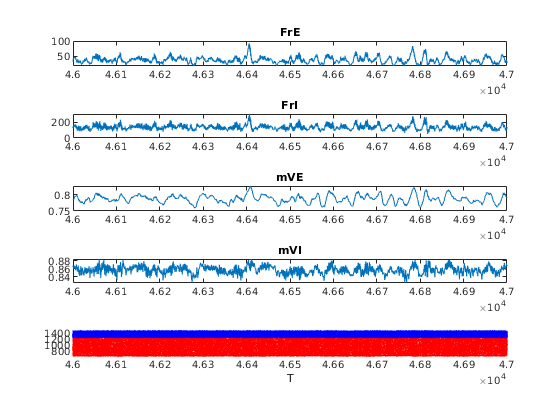


figure("Name",'Raster')
Xrange = [46000 47000];
subplot 511
plot(StatWin(1:end-Smth),SNWData.SpE/N_E/WinSize*1e3)
title('FrE');xlim(Xrange)
subplot 512
plot(StatWin(1:end-Smth),SNWData.SpI/N_I/WinSize*1e3)
title('FrI');xlim(Xrange)
subplot 513
plot(StatWin(1:end-Smth),SNWData.VE)
title('mVE');xlim(Xrange)
subplot 514
plot(StatWin(1:end-Smth),SNWData.VI)
title('mVI');xlim(Xrange)
subplot 515
hold on
%ENeu = floor(N_E/2):N_E; INeu = 1:floor(N_I/2);
SpETime = SpE(:,2);
SpENInd = SpE(:,1);
SpITime = SpI(:,2);
SpINInd = SpI(:,1);
scatter(SpETime, SpENInd,0.1 ,'r.')
scatter(SpITime, SpINInd+max(SpENInd) , 0.1,'b.')
xlim(Xrange); ylim([floor(N_E*2/3),N_E+floor(N_I/3)])
xlabel('T')

Spectrogram

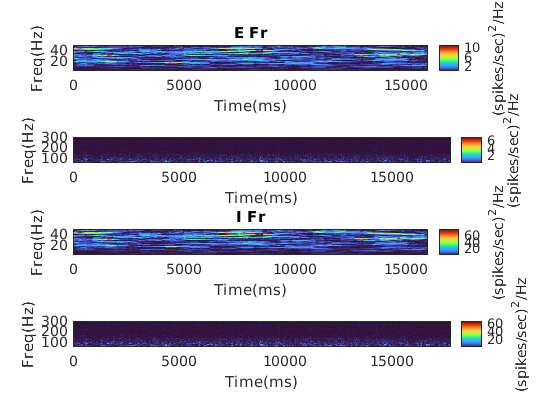

param1.spectrogram_timewindow = 2000;
param1.sdbin = T/WinNum;
param1.frequency_range = [1 50];
param1.duration = [];
param2 = param1; param2.frequency_range = [50,300];
param2.spectrogram_timewindow = 200;
figure('Name','Spectrogram')
subplot 411
spgE1=spectrogram(SNWData.SpE(15e4:24e4)/N_E/WinSize*1e3,param1);
title('E Fr')
subplot 412
spgE2=spectrogram(SNWData.SpE(15e4:24e4)/N_E/WinSize*1e3,param2);

%set(gca,'ColorScale','log')
subplot 413
spgI1=spectrogram(SNWData.SpI(15e4:24e4)/N_I/WinSize*1e3,param1);
title('I Fr')
subplot 414
spgI2=spectrogram(SNWData.SpI(15e4:24e4)/N_I/WinSize*1e3,param2);


%set(gca,'ColorScale','log')
